# Analisi del moto

Fasi del moto: 

FASE 1 : il braccio parte da fermo con accelereazione massima per portarsi alla velocità massima di wmax in 0,39s

in questa fase , avendo un'accelerazione massima di 10,8 rad/s^2

percorro uno spostamento angolare di **θ**1=0,82134 rad(1/2*alpha*(Ts)^2)

FASE 2: 

Il braccio si tiene alla velocità massima di 4,2 rad/s con accelerazione nulla per un tempo pari a 0,35 s(**θ2/w**) percorrendo uno spostamento **θ2=1,498 rad** (θ2=π-2*θ1)

FASE 3:

Il braccio decelera con accelerazione pari a 10,8rad/s^2 per portarsi da velocità massima di 4,2 rad/s a 0 percorrendo uno spostamento angolare θ3 = 0,821 rad

# SPECIFICHE:

Si definiscono ora alcune specifiche di progetto come la velocità massima di rotazione e il tempo necessario a raggiungerla.

clear 
clc

w_max = 4.2;%rad/sec
Ts = 0.39; %secondi
a_max=w_max/Ts;

# Calcolo inerzie e coppia

Il braccio è stato modellato come una sbarra sottile di 2Kg che ruota attorno a un'asse passante a 5 cm da un'estremità. All'estremo opposto troviamo invece un gripper di massa pari a 1Kg e un farmaco di massa pari a 50g. Si procede nei calcoli successivi a definire l'inerzia del sistema completo dato dai 3 contributi: braccio, gripper e farmaco. Dato il suo valore irrilevante , è stata trascurata l'inerzia del rotore del motore per il calcolo dell'inerzia Jtot.

Il braccio è stato modellato come una sbarra sottile e la sua inerzia è stata calcolata usando la seguente formula: I=1/12*M*L^2+M*d^2 con d che rappresenta la distanza tra il centro di massa e l'asse di rotazione e con L che invece rappresenta la lunghezza del braccio.

Per il gripper e il farmaco ho assunto di avere a che fare con due masse puntiformi il cui contributo in termini di inerzia è stato calcolato come M*L^2 con L che in questo caso rappresenta la distanza dall'asse di rotazione.

m_braccio=2;     
L_braccio=0.5;    
d_braccio=0.2;    
m_gripper=1;      
d=0.45;           
m_farmaco=0.05;    
J_braccio=0.083*m_braccio*(L_braccio^(2))+m_braccio*(d_braccio^2)

J_braccio = 0.1215

J_gripper=1*d^2

J_gripper = 0.2025

J_farmaco=m_farmaco*(d^2)

J_farmaco = 0.0101

J_tot = J_farmaco+J_gripper+J_braccio

J_tot = 0.3341



Ce = 0.1 ; % coppia esterna che modella disturbi legati al carico
Ctot = Ce + J_tot*a_max ; 

# Scelta motore

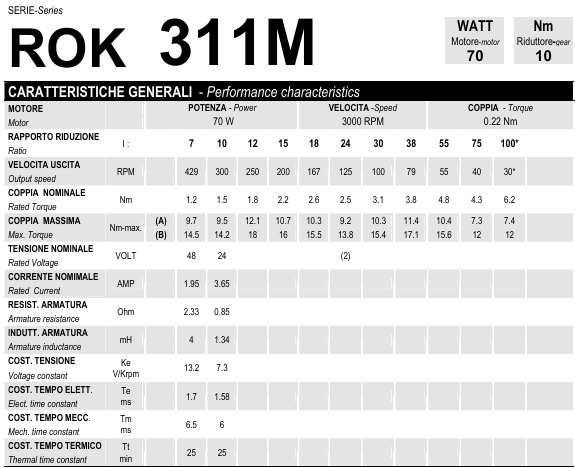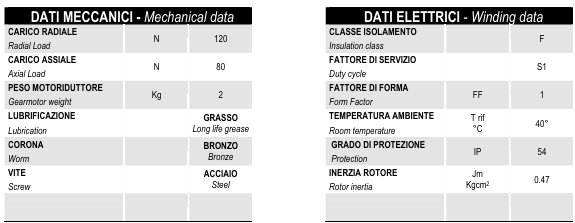

Ho scelto questo motore dato che con un fattore di riduzione pari a 55 sono riuscito a soddisfare le mie due esigenze su velocità(4,2rad/s=40RPM<55RPM) e su coppia

(3,7 Nm<4,8Nm). 

# calcolo dell'inerzia vista dal motore 

%raccogliamo i parametri del motore
Jm= 0.47e-4

Jm = 4.7000e-05

w_max_motore = 314.159265

w_max_motore = 314.1593

a_max_motore= w_max_motore/Ts;
Ra = 0.85;
La = 1.34e-3;
kv = 0.0697;
kt = 0.0697;
Cnom = 0.22;
Vnom = 24;
Inom = 3.65; 


%calcolo coppia a monte del riduttore
%Ctot_2 = Ctot/55 + (J_tot*a_max)/55 + Jm*a_max_motore
Ctot_2 = Ctot/55 + Jm*a_max_motore

Ctot_2 = 0.1051

%inerzia equivalente vista dal motore per il suo modello
Jeq=Ctot_2/a_max_motore;


potElettNom = Vnom*Inom;
potMecc = Cnom*w_max_motore;% Coppia nominale * w nominale
potDissElettr = Ra*Inom^2;
potDissMecc = potElettNom-potDissElettr-potMecc;
B = potDissMecc/w_max_motore^2;

# FDT motore

Raccogliendo alcuni parametri dal datasheet come resistenza di armatura

Pel = tf(1,[La Ra]);
Pmec = tf(1,[Jeq B]);
Ls = kt*series(Pel,Pmec);
M = feedback(Ls,kv)


M =
 
                 0.0697
  ------------------------------------
  1.748e-07 s^2 + 0.000111 s + 0.00492
 
Continuous-time transfer function.
Model Properties



Iamax = Ctot_2/kt % Ampere

Iamax = 1.5079


Eg = kv*w_max_motore % Volt

Eg = 21.8969


Va = Eg+Ra*Iamax % Volt

Va = 23.1786

# Simulazione a vuoto

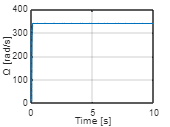


%simulazione
model = 'motor';
load_system(model);
Tsim = 10;  % Durata della simulazione
set_param(model, 'StopTime', num2str(Tsim));
out = sim(model);
w_vuoto = out.w_sim1;
ia_vuoto = out.i_sim1;
qm_vuoto = out.C_sim1;

% Salvo i risultati in un file
save('motor_vuoto.mat', 'w_vuoto', 'ia_vuoto', 'qm_vuoto');

plot(w_vuoto.Time, w_vuoto.Data,LineWidth=1.5)
grid on
xlabel("Time [s]")
ylabel("Ω [rad/s]")

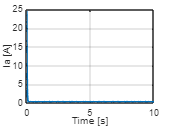



plot(ia_vuoto.Time, ia_vuoto.Data,LineWidth=1.5) 
grid on
xlabel("Time [s]")
ylabel("Ia [A]")

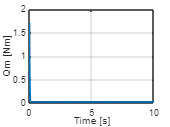



plot(qm_vuoto.Time, qm_vuoto.Data,LineWidth=1.5)
grid on
xlabel("Time [s]")
ylabel("Qm [Nm]")

# Amplificatore di tensione

dcvolt =5 ;
kamp = (Va+(20*Va/100))/dcvolt;  % costante di amplificazione
Vctr = Va/kamp;
V_kp=0.9*Vctr;

# Limitatore di corrente

ia_limite = 1.2*Inom;
klim = dcvolt/(0.2*Inom);


# simulazioni con limitatore e amplificatore

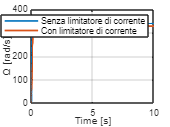

load('motor_vuoto.mat')

model = 'Limitatore';
load_system(model);
Tsim = 10;  % Durata della simulazione
set_param(model, 'StopTime', num2str(Tsim));
out = sim(model);

plot(w_vuoto.Time, w_vuoto.Data,LineWidth=1.5) %plot velocità
hold on
plot(out.w_sim2.Time, out.w_sim2.Data,LineWidth=1.5)
grid on
legend("Senza limitatore di corrente","Con limitatore di corrente")
xlabel("Time [s]")
ylabel("Ω [rad/s]")

hold off

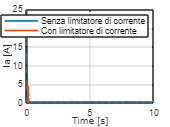


plot(ia_vuoto.Time, ia_vuoto.Data,LineWidth=1.5) %plot corrente di armatura
hold on
plot(out.i_sim2.Time, out.i_sim2.Data,LineWidth=1.5) 
grid on
legend("Senza limitatore di corrente","Con limitatore di corrente")
xlabel("Time [s]")
ylabel("Ia [A]")

hold off

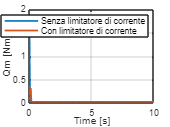


plot(qm_vuoto.Time, qm_vuoto.Data,LineWidth=1.5) %plot coppia motrice
hold on
plot(out.C_sim2.Time, out.C_sim2.Data,LineWidth=1.5)
grid on
legend("Senza limitatore di corrente","Con limitatore di corrente")
xlabel("Time [s]")
ylabel("Qm [Nm]")

hold off

# Dinamo tachimetrica

kdt=dcvolt/w_max_motore;

# Kp

model = 'Controllore';
load_system(model);
Tsim = 10;

%input a simulazione
%input_step_amplitude = High_voltage;                %valore max d'input                                                 

%specifiche desiderate
Ripple_Max = 0.05 * Inom

Ripple_Max = 0.1825

Ia_max = 1.20 * Inom

Ia_max = 4.3800


kp = 20;             % Valore iniziale di Kp
ki = 0;               % Annullo parte integrativa

kp_step = 2;          % Divido kp per kp_step
max_iter = 20;        % Numero massimo di iterazioni
iter = 0;


% Inizializzazione array per salvare i risultati
corrente_array = {}; 
tempo_array = {};
ki_array = {};


% Inizializzazione
ripple_corrente = Inf;
max_corrente = Inf;


% Inizio ciclo di ottimizzazione
while (ripple_corrente > Ripple_Max || max_corrente >Ia_max) && iter < max_iter
    iter = iter + 1;

    % Simulazione
    set_param(model, 'StopTime', num2str(Tsim));
    out = sim(model);

     % Estrazione dei segnali
    corrente_array{iter} = out.i_sim.Data;
    tempo_array{iter} = out.i_sim.Time;
    kp_array{iter} = kp;
    
    
    %calcolo del picco
    max_corrente = max(corrente_array{iter});

    % Selezione dell'ultimo decimo della simulazione (elimino transitorio)
    indice_finale = tempo_array{iter} > Tsim * 0.9;
    corrente_finale = corrente_array{iter}(indice_finale);
    
    % Calcolo del ripple solo in quell'intervallo
    ripple_corrente = max(corrente_finale) - min(corrente_finale);
   

    % Stampa stato
    fprintf('Iterazione %d: Kp = %.2f, Ripple = %.4f, CorrenteMax = %.4f \n', iter, kp, ripple_corrente, max_corrente);

    % Aggiorno Kp
    if ripple_corrente > Ripple_Max || max_corrente >Ia_max
        kp = kp / kp_step;
    end
end

Iterazione 1: Kp = 20.00, Ripple = 1.2600, CorrenteMax = 4.9963 
Iterazione 2: Kp = 10.00, Ripple = 0.8185, CorrenteMax = 4.9963 
Iterazione 3: Kp = 5.00, Ripple = 0.7492, CorrenteMax = 4.9963 
Iterazione 4: Kp = 2.50, Ripple = 0.1702, CorrenteMax = 4.9963 
Iterazione 5: Kp = 1.25, Ripple = 0.0844, CorrenteMax = 4.9963 
Iterazione 6: Kp = 0.62, Ripple = 0.0394, CorrenteMax = 4.7267 
Iterazione 7: Kp = 0.31, Ripple = 0.0195, CorrenteMax = 4.5030 
Iterazione 8: Kp = 0.16, Ripple = 0.0113, CorrenteMax = 4.3539 


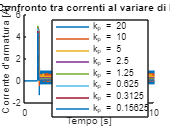



%plot del procedimento
N = numel(corrente_array);  % Numero di plot

figure;
hold on
for i = 1:N
    plot(tempo_array{i}, corrente_array{i}, 'DisplayName', ['k_p = ' num2str(kp_array{i})]);
end
xlabel('Tempo [s]');
ylabel("Corrente d'armatura [A]");
title('Confronto tra correnti al variare di kp');
legend;
hold off;

% 
% filename = fullfile(plot_folder, 'confrontoCorrentiKp.png');
% saveas(gcf, filename);
% 



% Output finale
fprintf('\nValore finale di Kp: %.2f con Ripple = %.4f e corrente max = %.4f\n', kp, ripple_corrente, max_corrente);


Valore finale di Kp: 0.16 con Ripple = 0.0113 e corrente max = 4.3539


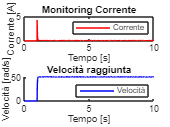


ki = 0;
dt=0.01;
% Modello
model = 'Controllore';
load_system(model);
Tsim = 6;



% Simulazione
out = sim(model);

% Estrazione dei segnali
velocita = out.w_sim.Data;
tempo = out.w_sim.Time;
corrente = out.i_sim.Data;
% riferimento = squeeze(out.rif_sim.Data);


% Plot dei risultati
figure;

subplot(2, 1, 1);
plot(tempo, corrente, 'r', 'DisplayName', 'Corrente');
title('Monitoring Corrente');
xlabel('Tempo [s]');
ylabel('Corrente [A]');
legend;

subplot(2, 1, 2);
hold on;
plot(tempo, velocita, 'b', 'DisplayName', 'Velocità');
title('Velocità raggiunta');
xlabel('Tempo [s]');
ylabel('Velocità [rad/s]');
legend('Location', 'southeast');
hold off;

# ki


% modello
model = 'Controllore';
load_system(model);
Tsim = 10;
set_param(model, 'StopTime', num2str(Tsim));
out = sim(model);

%specifiche desiderate
SovrMax = 0.2;

ki = 2;
ki_step = 1.3;        % moltiplico ki per ki_step
max_iter = 20;        % Numero massimo di iterazioni
iter = 0;

% Inizializzazione array per salvare i risultati
velocita_array = {}; 
tempo_array = {};
ki_array = {};


% Inizializzazione
sovraelongazione = -Inf;
sovraelongazione_precedente = -Inf;
ki_precedente = -1;


% Inizio ciclo di ottimizzazione
while sovraelongazione < SovrMax && iter < max_iter
    iter = iter + 1;

    % Simulazione
    set_param(model, 'StopTime', num2str(Tsim));
    out = sim(model);

    % Estrazione dei segnali
    velocita_array{iter} = out.w_sim.Data;
    tempo_array{iter} = out.w_sim.Time;
    ki_array{iter} = ki;
    
    
    %calcolo del picco e del regime
    max_vel = max(velocita_array{iter});
    regime = velocita_array{iter}(end);
    xx=find(tempo_array{iter}>=4.9,1);
    vel_prec=velocita_array{iter}(xx);
    
    sovraelongazione = (max_vel - regime) /(regime-vel_prec);
    
    
    % Stampa stato
    fprintf('Iterazione %d: Ki = %.2f, sovraelongazione = %.4f\n', iter, ki, sovraelongazione);

    % Aggiorno Ki
    if sovraelongazione < SovrMax 
        %salvo le variabili perché se al prossimo ciclo supererò SovrMax
        %saranno quelle valide
        ki_precedente = ki;
        sovraelongazione_precedente = sovraelongazione;
        
        %aggiornamento
        ki = ki * ki_step;     
    end
end

Iterazione 1: Ki = 2.00, sovraelongazione = 0.0001
Iterazione 2: Ki = 2.60, sovraelongazione = 0.0000
Iterazione 3: Ki = 3.38, sovraelongazione = 0.0002
Iterazione 4: Ki = 4.39, sovraelongazione = 0.0003
Iterazione 5: Ki = 5.71, sovraelongazione = 0.0003
Iterazione 6: Ki = 7.43, sovraelongazione = 0.0003
Iterazione 7: Ki = 9.65, sovraelongazione = 0.0003
Iterazione 8: Ki = 12.55, sovraelongazione = 0.0004
Iterazione 9: Ki = 16.31, sovraelongazione = 0.0024
Iterazione 10: Ki = 21.21, sovraelongazione = 0.0220
Iterazione 11: Ki = 27.57, sovraelongazione = 0.0590
Iterazione 12: Ki = 35.84, sovraelongazione = 0.9533


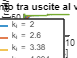


%sono andato oltre SovrMax%, prendo le precedenti
ki = ki_precedente;
sovraelongazione = sovraelongazione_precedente;


%plot del procedimento
N = numel(velocita_array);  % Numero di plot

figure;
hold on
for i = 1:N
    plot(tempo_array{i}, velocita_array{i}, 'DisplayName', ['k_i = ' num2str(ki_array{i})]);
end
xlabel('Tempo [s]');
ylabel('Velocità [rad/s]');
title('Confronto tra uscite al variare di ki');
legend;
hold off;


% filename = fullfile(plot_folder, 'confrontoUsciteKi.png');
% saveas(gcf, filename);



% Output finale
fprintf('\nValore finale di Ki: %.2f con sovrelongazione %.4f\n', ki, sovraelongazione );


Valore finale di Ki: 27.57 con sovrelongazione 0.0590


# Simulazione controllore

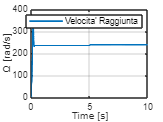



model = 'Controllore';
load_system(model);
Tsim = 10;  % Durata della simulazione
set_param(model, 'StopTime', num2str(Tsim));
out = sim(model);
vel = out.w_sim;
corr = out.i_sim;

plot(vel.Time, vel.Data,LineWidth=1.5)
grid on
legend("Velocita' Raggiunta")
xlabel("Time [s]")
ylabel("Ω [rad/s]")
% % 
hold off

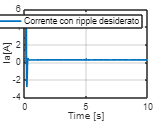

% controllosenza = out.controllosenzaAntiwindup;
% % Salvo i risultati in un file
% save('senza_antiwindup.mat', 'vel', 'corr','controllosenza');


% plot(velocita.Time, velocita.Data,LineWidth=1.5) %plot velocità


plot(corr.Time, corr.Data,LineWidth=1.5) %plot corrente di armatura
grid on
% plot(out.i_sim.Time, out.i_sim.Data,LineWidth=1.5) 
grid on
legend("Corrente con ripple desiderato")
xlabel("Time [s]")
ylabel("Ia[A]")

hold off

# funzione di trasferimento a ciclo chiuso con controllore

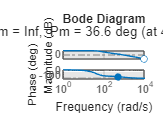

PI = tf([kp ki], [1 0]);
L = kamp*series(PI, M); 
T_s = L/(1+kdt*L);

figure, margin(T_s)    %luogo delle radici
grid on

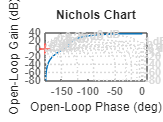


%% Nichols
nichols(T_s)
ngrid

# Anti wind up

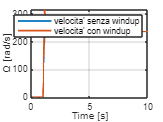

load('senza_antiwindup.mat')

model = 'Antiwindup';
load_system(model);
Tsim = 10;  % Durata della simulazione
set_param(model, 'StopTime', num2str(Tsim));
out = sim(model);


plot(vel.Time, vel.Data,LineWidth=1.5) %plot velocità
hold on
plot(out.w_sim.Time, out.w_sim.Data,LineWidth=1.5)
grid on
legend("velocita' senza windup","velocita' con windup")
xlabel("Time [s]")
ylabel("Ω [rad/s]")

hold off

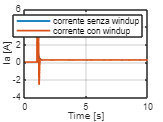


plot(corr.Time, corr.Data,LineWidth=1.5) %plot corrente di armatura
hold on
plot(out.i_sim.Time, out.i_sim.Data,LineWidth=1.5) 
grid on
legend("corrente senza windup","corrente con windup")
xlabel("Time [s]")
ylabel("Ia [A]")

hold off


% plot(controllosenza.Time, controllosenza.Data,LineWidth=1.5) %plot corrente di armatura
% hold on
% plot(out.controllo.Time, out.controllo.Data,LineWidth=1.5) 
% grid on
% legend("Controllo senza Antiwindup","Controllo con Antiwindup")
% xlabel("Time [s]")
% ylabel("Controllo[V]")
% 
% hold off
% 


# Feedforewad



kff = kv/(kamp*kdt);
S_new = Inom*Ra/kamp

S_new = 0.5577

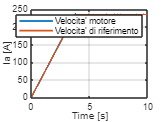

S_new2 = S_new + 20*S_new/100;


model = 'feedforeward';
load_system(model);
Tsim = 10;  % Durata della simulazione
set_param(model, 'StopTime', num2str(Tsim));
out = sim(model);






plot(out.w_sim.Time, out.w_sim.Data,LineWidth=1.5) %plot corrente di armatura
hold on
plot(out.riferimento.Time, out.riferimento.Data,LineWidth=1.5) 
grid on
legend("Velocita' motore","Velocita' di riferimento")
xlabel("Time [s]")
ylabel("Ia [A]")

hold off

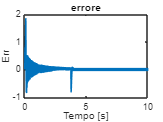



figure;
plot(out.errore)
title("errore")
xlabel('Tempo [s]');
ylabel("Err");

% Progetto rampa

% Progetto profilo di accelerazione/velocità/posizione
x0 = 0;
xf = 3.14;


s_Ts = 1/2*a_max*Ts^2; % spazio percorso durante il tempo di salita

Td = Ts; % tempo di discesa
s_Td = s_Ts; % spazio percorso durante il tempo di discesa

s_regime = (xf-x0)-(s_Ts+s_Td);
T_regime = s_regime/w_max;


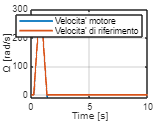


%plot immagini finali


out = sim('Asservimento.slx'); 
plot(out.w_sim.Time, out.w_sim.Data,LineWidth=1.5) %plot corrente di armatura
hold on
plot(out.velocita.Time, out.velocita.Data,LineWidth=1.5) 
grid on
legend("Velocita' motore","Velocita' di riferimento")
xlabel("Time [s]")
ylabel("Ω [rad/s]")

hold off

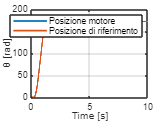



plot(out.posizione.Time, out.posizione.Data,LineWidth=1.5) %plot corrente di armatura
hold on
plot(out.refpos.Time, out.refpos.Data,LineWidth=1.5) 
grid on
legend("Posizione motore","Posizione di riferimento")
xlabel("Time [s]")
ylabel("θ [rad]")

hold off

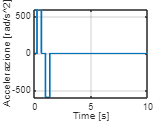






plot(out.accelerazione.Time, out.accelerazione.Data,LineWidth=1.5)
grid on
xlabel("Time [s]")
ylabel("Accelerazione [rad/s^2]")

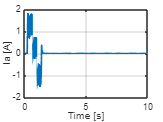


plot(out.i_sim.Time, out.i_sim.Data,LineWidth=1.5)
grid on
xlabel("Time [s]")
ylabel("Ia [A]")